# **PRESENTACIÓN FINAL (Cinemática Diferencial de Piernas)**

**Jesús Alejandro Gómez Bautista | A01736171**

## **PARTE I**

## **EJERCICIO 1 ---------------------------**

**Obtener **la matriz de  transformación **homogénea global T, empleando variables simbólicas** de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base). Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final.

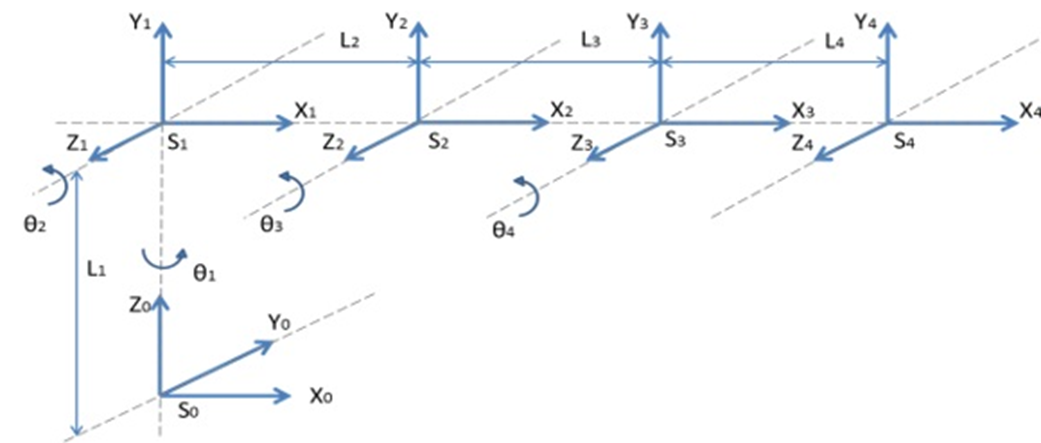 

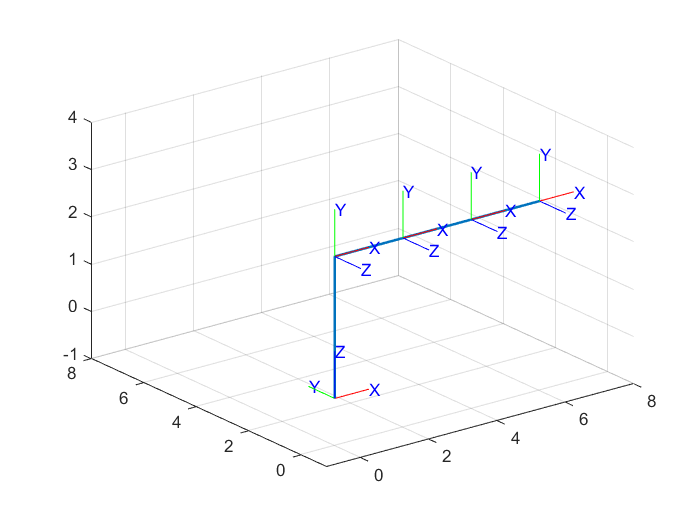

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 3]);
H2=SE3([2 0 0]);
H3=SE3([2 0 0]);
H4=SE3([2 0 0]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4;  %Matriz de transformación homogenea global de 4 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 0 6];
y=[0 0 0];
z=[0 3 3];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 8 -1 8 -1 4]); grid on;
hold on;

 %Graficamos la trama absoluta o global 
 trplot(H0,'rgb','axis', [-1 8 -1 8 -1 4])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0, H1,'rgb','axis', [-1 8 -1 8 -1 4])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 8 -1 8 -1 4])
% % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H20, H30,'rgb','axis', [-1 8 -1 8 -1 4])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H30, H40,'rgb','axis', [-1 8 -1 8 -1 4])

**Matriz de transformación global T**

 disp(H40)

    1         0         0         6
    0         0        -1         0
    0         1         0         3
    0         0         0         1


## **EJERCICIO 2 ---------------------------**

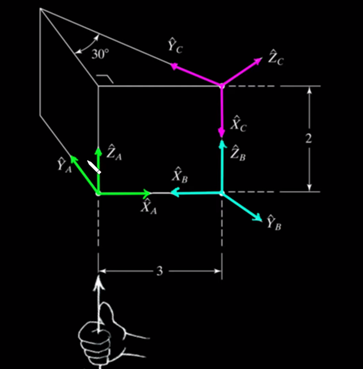

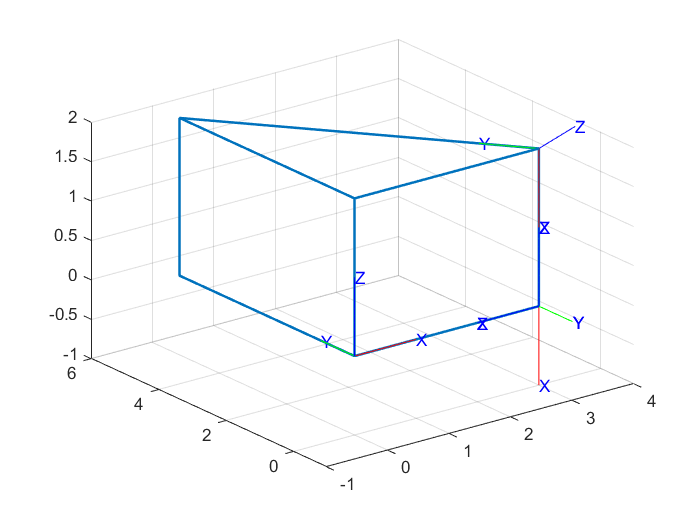

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotz(pi), [3 0 0]);
H2=SE3(roty(pi/2), [0 0 0]);
H3=SE3(rotx(150*pi/180), [-2 0 0]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 3 3 0 0 0     0     0 0     3];
y=[0 0 0 0 0 5.196 5.196 0 5.196 0];
z=[0 0 2 2 0 0     2     2 2     2];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])

**Matriz de transformación global T**

 disp(H30)

     0      -0.5     0.866         3
     0     0.866       0.5         0
    -1         0         0         2
     0         0         0         1


## EJERCICIO 3 **---------------------------**

#### 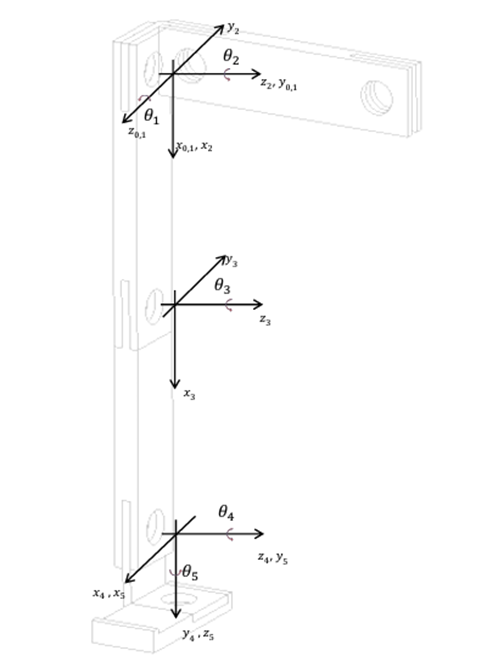

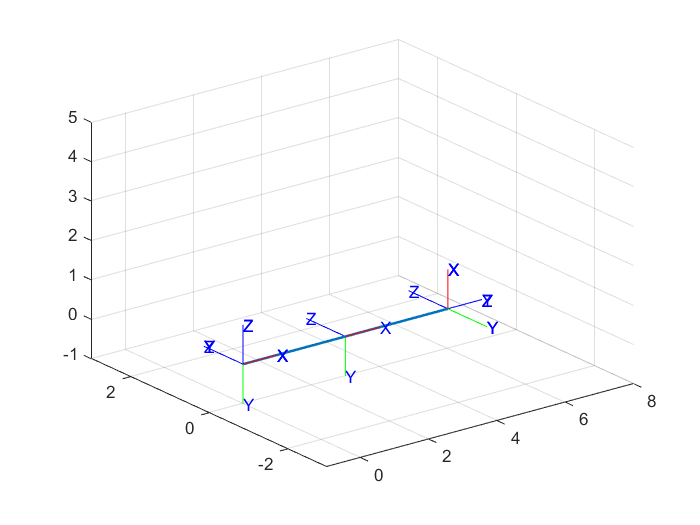

 %Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotz(2*pi),[0 0 0]);
H2=SE3(rotx(-pi/2), [0 0 0]);
H3=SE3(rotz(2*pi),[3 0 0]);
H4=SE3(rotz(-pi/2), [3 0 0]);
H5=SE3(rotx(-pi/2), [0 0 0]);
H6=SE3(rotz(2*pi), [0 0 0]);


H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4; %Matriz de transformación homogenea global de 4 a 0 
H50= H40*H5; %Matriz de transformación homogenea global de 5 a 0 
H60= H50*H6; %Matriz de transformación homogenea global de 6 a 0 


%Coordenadas de la estructura de translación y rotación
x=[0  6];
y=[0  0];
z=[0  0];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 8 -3 3 -1 5]); grid on;
hold on;

 %Graficamos la trama absoluta o global 
 trplot(H0,'rgb','axis', [-1 8 -3 3 -1 5])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0, H1,'rgb','axis', [-1 8 -3 3 -1 5])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 8 -3 3 -1 5])
% % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H20, H30,'rgb','axis', [-1 8 -3 3 -1 5])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H30, H40,'rgb','axis', [-1 8 -3 3 -1 5])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H40, H50,'rgb','axis', [-1 8 -3 3 -1 5])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H50, H60,'rgb','axis', [-1 8 -3 3 -1 5])

**Matriz de transformación global T**

 disp(H60)

    -2.449e-16-2.449e-16         1         6
     2.449e-16        -1-2.449e-16 -1.47e-15
             1 2.449e-16 2.449e-16 7.348e-16
             0         0         0         1


## **EJERCICIO 4. (Modelo de la pierna) ---------------------------**

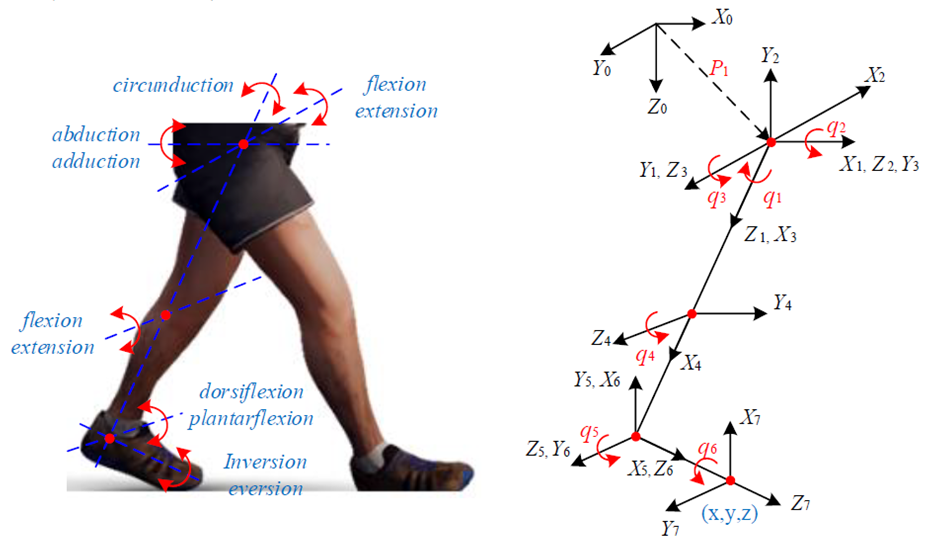

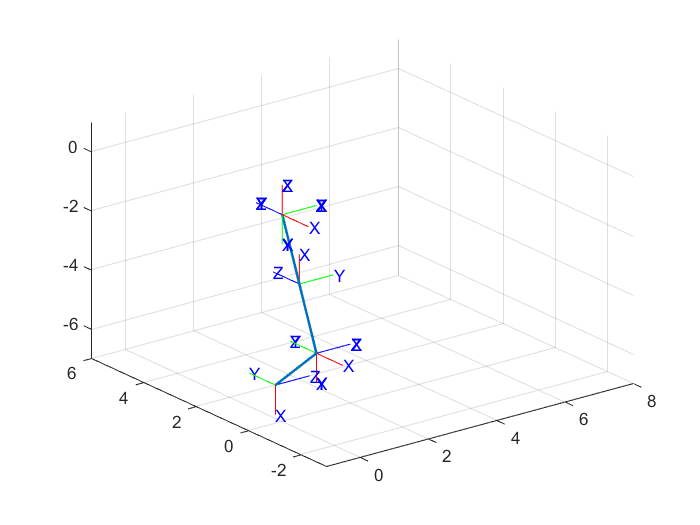

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
%%% Del marco 1 al 2
H1=SE3(roty(pi/2),[0 0 0]);
H2=SE3(rotz(-pi/2), [0 0 0]);

%%% Del marco 2 al 3
H3=SE3(roty(-pi/2),[0 0 0]);
H4=SE3(rotz(-pi/2), [0 0 0]);

%%% Del marco 4 al 5
H5=SE3([-2.5 0.5 0]);

%%% Del marco 5 al 6
H6=SE3(rotz(pi/2), [-2.5 0.5 0]);

%%% Del marco 5 al 6
H7=SE3(roty(pi/2), [0 0 0]);
H8=SE3(rotz(pi/2), [0 0 0]);

%%% Del marco 6 al 7
H9=SE3([.7 0 -1.2]);


H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4; %Matriz de transformación homogenea global de 4 a 0 
H50= H40*H5; %Matriz de transformación homogenea global de 5 a 0 
H60= H50*H6; %Matriz de transformación homogenea global de 6 a 0 
H70= H60*H7;
H80= H70*H8;
H90= H80*H9;


%Coordenadas de la estructura de translación y rotación
x=[0   1   -.2];
y=[0   0    0];
z=[0  -5   -5.7];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 8 -3 6 -7 1]); grid on;
hold on;

 %Graficamos la trama absoluta o global 
 trplot(H0,'rgb','axis', [-1 8 -3 6 -7 1])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0, H1,'rgb','axis', [-1 8 -3 6 -7 1])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 8 -3 6 -7 1])
% % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H20, H30,'rgb','axis', [-1 8 -3 6 -7 1])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H30, H40,'rgb','axis', [-1 8 -3 6 -7 1])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H40, H50,'rgb','axis', [-1 8 -3 6 -7 1])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H50, H60,'rgb','axis', [-1 8 -3 6 -7 1])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H60, H70,'rgb','axis', [-1 8 -3 6 -7 1])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H70, H80,'rgb','axis', [-1 8 -3 6 -7 1])
 % % %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H80, H90,'rgb','axis', [-1 8 -3 6 -7 1])

**Matriz de transformación global T**

 disp(H90)

     0         0         1      -0.2
     0         1         0         0
    -1         0         0      -5.7
     0         0         0         1


## PARTE II.

## CINEMÁTICA DIFERENCIAL SIMBÓLICA (Pierna)

- **Desarrollar **el modelo de **cinemática diferencial simbólica** para cada uno de los sistemas descritos anteriormente y obtener los vectores de la **velocidad angular y velocidad lineal** aplicando variables simbólicas para su análisis en cada caso.

- **mplementar **el código requerido para generar el cálculo de las matrices **homogéneas simbólicas (H1, H2, H3, etc.),** la matriz de **transformación simbólica (T) **y los vectores de **velocidades simbólicas (v, w) **de cada sistema.

 % Limpieza de pantalla
clear all
close all
clc

%% DECLARACIÓN DE VARIABLES SIMBÓLICAS %%
% Donde l1 es igual a la longitud de la pierna
% Donde l2 es igual a la longitud de la pantorrilla
% Donde l3 es igual a la longitud del pie

syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) th7(t) t l1 l2 l3

% Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP = [0 0 0 0 0 0 0];

% Creamos el vector de coordenadas articulares
Q = [-th1, th2, th3, th4, th5, th6, th7];
% disp('Coordenadas generalizadas');
% pretty(Q);

% Creamos el vector de velocidades generalizadas
Qp = diff(Q, t);
% disp('Velocidades generalizadas');
% pretty(Qp);

% Número de grado de libertad del robot
GDL = size(RP, 2);
GDL_str = num2str(GDL);

#### Rotaciones de las articulaciones de las piernas

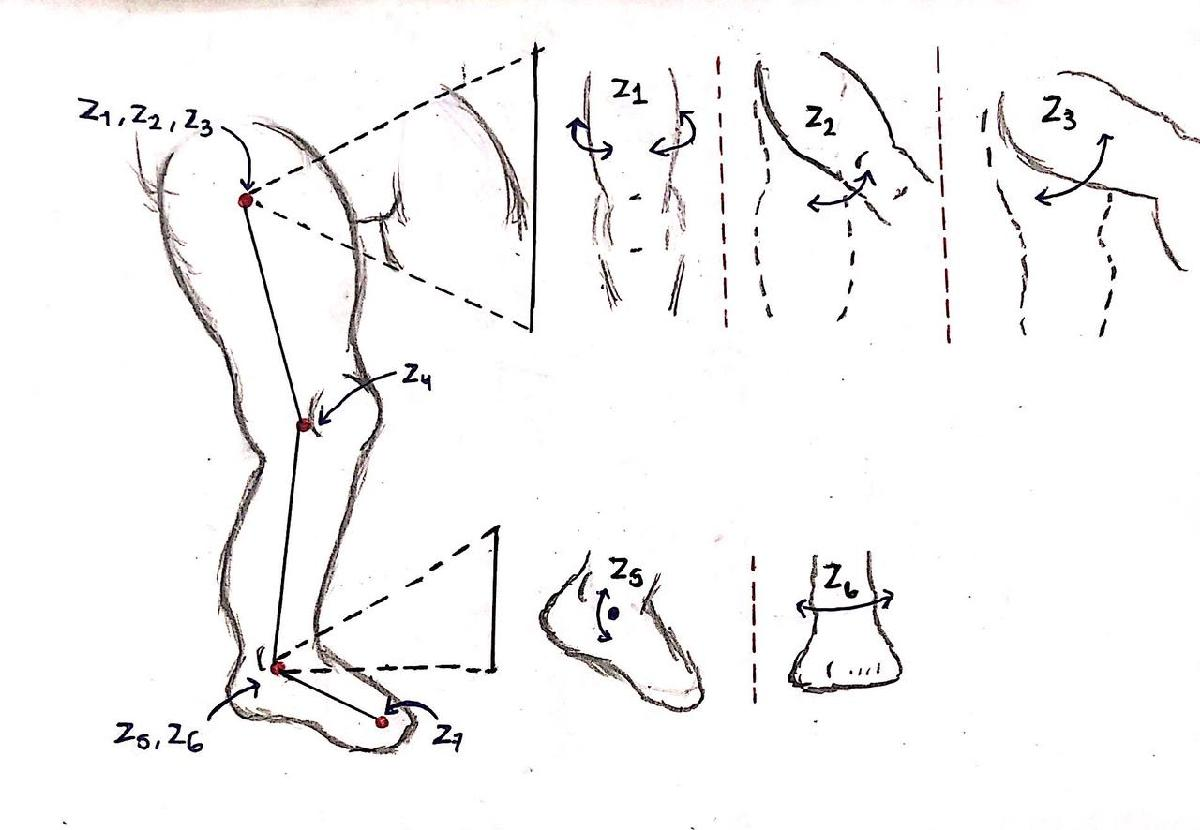

% Rotaciones en el eje Z de cada articulación de la pierna

articulacion_Z1 = [cos(-th1) -sin(-th1)  0;
                   sin(-th1)  cos(-th1)  0;
                   0         0         1];

articulacion_Z2 = [cos(th2) -sin(th2)  0;
                   sin(th2)  cos(th2)  0;
                   0         0         1];

articulacion_Z3 = [cos(th3) -sin(th3)  0;
                   sin(th3)  cos(th3)  0;
                   0         0         1];

articulacion_Z4 = [cos(th4) -sin(th4)  0;
                   sin(th4)  cos(th4)  0;
                   0         0         1];

articulacion_Z5 = [cos(th5) -sin(th5)  0;
                   sin(th5)  cos(th5)  0;
                   0         0         1];

articulacionZ6 = [cos(th6) -sin(th6)  0;
                   sin(th6)  cos(th6)  0;
                   0         0         1];

articulacion_Z7 = [cos(th7) -sin(th7)  0;
                   sin(th7)  cos(th7)  0;
                   0         0         1];

#### Rotaciones adicionales (Pasos de marco en marco)

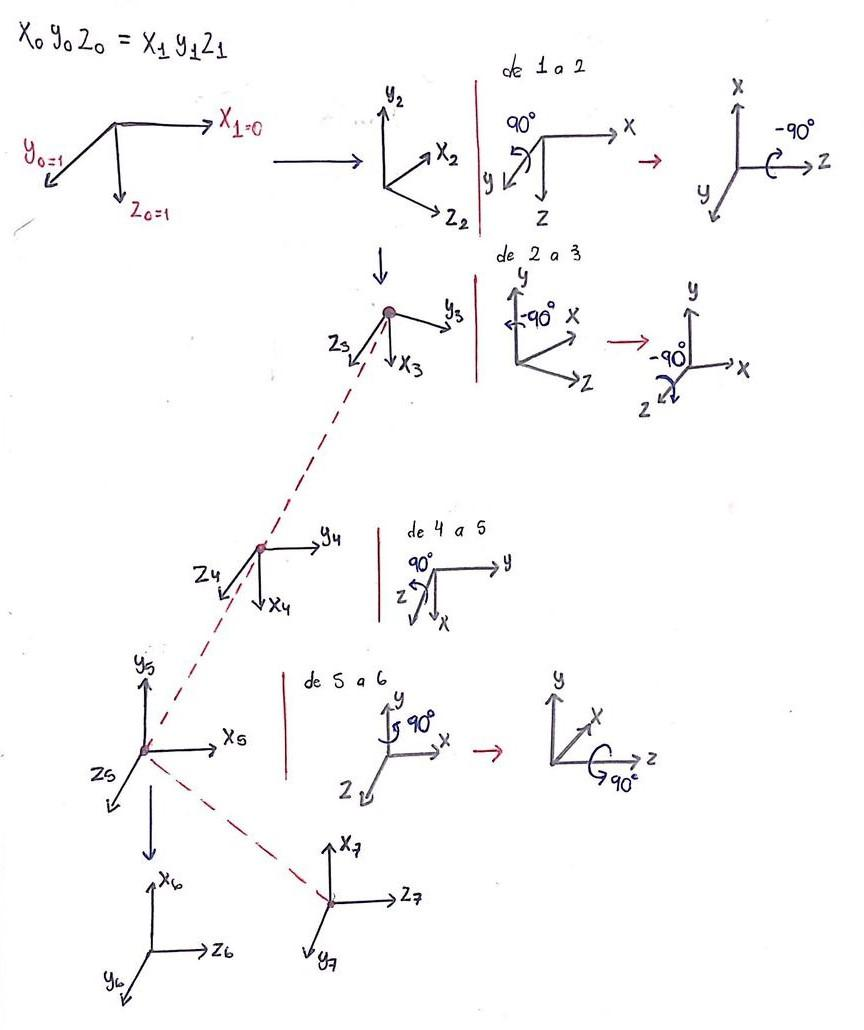

% La mayoría de ellas con valores iguales a 90° o -90°
% Según las necesidades de cada marco para trasladar la posición 
% de nuestro z en el eje correspondiente.

roty90 = [0 0 1;
          0 1 0;
         -1 0 0];

rotym90 = [0 0 -1;
           0 1  0;
           1 0  0];

rotz90 = [0 -1 0;
          1  0 0;
          0  0 1];

rotzm90 = [0 1 0;
         -1 0 0;
          0 0 1];

#### Posición de las articulaciones

% Inicialización de matrices de rotación y posiciones de cada articulación
P = sym(zeros(3, 1, GDL));
R = sym(zeros(3, 3, GDL));

% Articulación 1 
% Posición de la articulación 1 respecto a 0
P(:,:,1) = [0; 0; 0];
% Matriz de rotación de la junta 1 respecto a 0
R(:,:,1) = articulacion_Z1;

% Articulación 2
% Posición de la articulación 2 respecto a 1
P(:,:,2) = [0; 0; 0];
% Matriz de rotación de la junta 2 respecto a 1
R(:,:,2) = roty90*rotzm90*articulacion_Z2;

% Articulación 3 
% Posición de la articulación 3 respecto a 2
P(:,:,3) = [0; 0; 0];
% Matriz de rotación de la junta 3 respecto a 2
R(:,:,3) = rotym90*rotzm90*articulacion_Z3;

% Articulación 4
% Posición de la articulación 4 respecto a 3
P(:,:,4) = [l1; 0; 0];
% Matriz de rotación de la junta 4 respecto a 3
R(:,:,4) = articulacion_Z4;

% Articulación 5
% Posición de la articulación 5 respecto a 4
P(:,:,5) = [l2; 0; 0];
% Posición de la articulación 5 respecto a 4
R(:,:,5) = roty90*articulacion_Z5;

% Articulación 6
% Posición de la articulación 6 respecto a 5
P(:,:,6) = [0; 0; 0];
% Posición de la articulación 6 respecto a 5
R(:,:,6) = roty90*rotz90*articulacionZ6;

% Articulación 7
% Posición de la articulación 7 respecto a 6
P(:,:,7) = [l3; 0; 0];
% Posición de la articulación 7 respecto a 6
R(:,:,7) = articulacion_Z7;

% Creamos un vector de ceros
Vector_Zeros = zeros(1, 3);

#### Matrices de transformación locales y globales

% Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
% Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
% Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL) = P(:,:,GDL); 
% Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL) = R(:,:,GDL); 

for i = 1:GDL
    i_str = num2str(i);
    % disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    % pretty(A(:,:,i));

    % Globales
    try
       T(:,:,i) = T(:,:,i-1) * A(:,:,i);
    catch
       T(:,:,i) = A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i) = T(1:3, 1:3, i);
    PO(:,:,i) = T(1:3, 4, i);
    % pretty(RO(:,:,i));
    % pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/  cos(th1(t)), sin(th1(t)), 0, 0 \
|                                 |
| -sin(th1(t)), cos(th1(t)), 0, 0 |
|                                 |
|       0,           0,      1, 0 |
|                                 |
\       0,           0,      0, 1 /



Matriz de Transformación global T2


/ -cos(th2(t)) sin(th1(t)), sin(th1(t)) sin(th2(t)),  cos(th1(t)), 0 \
|                                                                    |
| -cos(th1(t)) cos(th2(t)), cos(th1(t)) sin(th2(t)), -sin(th1(t)), 0 |
|                                                                    |
|       -sin(th2(t)),             -cos(th2(t)),            0,      0 |
|                                                                    |
\             0,                       0,                  0,      1 /



Matriz de Transformación global T3


[[cos(th1(t)) sin(th3(t)) - cos(th3(t)) sin(th1(t)) sin(th2(t)), cos(th1(t)) cos(th3(t)) + sin(th1(t)) sin(th2(t)) sin(th3(t)),

  cos(th2(t)) sin(th1(t)), 0],

  [- sin(th1(t)) sin(th3(t)) - cos(th1(t)) cos(th3(t)) sin(th2(t)), cos(th1(t)) sin(th2(t)) sin(th3(t)) - cos(th3(t)) sin(th1(t)),

  cos(th1(t)) cos(th2(t)), 0], [cos(th2(t)) cos(th3(t)), -cos(th2(t)) sin(th3(t)), sin(th2(t)), 0],

  [0, 0, 0, 1]]



Matriz de Transformación global T4


/  cos(th4(t)) #1 + sin(th4(t)) #4,  cos(th4(t)) #4 - sin(th4(t)) #1, cos(th2(t)) sin(th1(t)),            l1 #1           \
|                                                                                                                         |
| - cos(th4(t)) #2 - sin(th4(t)) #3, sin(th4(t)) #2 - cos(th4(t)) #3, cos(th1(t)) cos(th2(t)),           -l1 #2           |
|                                                                                                                         |
|        cos(th2(t)) cos(#5),              -cos(th2(t)) sin(#5),            sin(th2(t)),       l1 cos(th2(t)) cos(th3(t)) |
|                                                                                                                         |
\                 0,                                0,                           0,                         1             /

where

   #1 == cos(th1(t)) sin(th3(t)) - cos(th3(t)) sin(th1(t)) sin(th2(t))

   #2 == sin(th1(t)) sin(th3(t)) + cos(th1(t)) cos(t

Matriz de Transformación global T5


[[sin(th5(t)) #3 - cos(th2(t)) cos(th5(t)) sin(th1(t)), cos(th5(t)) #3 + cos(th2(t)) sin(th1(t)) sin(th5(t)), #4, l2 #4 + l1 #7],

  [- sin(th5(t)) #2 - cos(th1(t)) cos(th2(t)) cos(th5(t)), cos(th1(t)) cos(th2(t)) sin(th5(t)) - cos(th5(t)) #2, - #6 - #5, - l2 (#6 + #5) - l1 #10],

  [- cos(th5(t)) sin(th2(t)) - cos(th2(t)) sin(th5(t)) sin(#1), sin(th2(t)) sin(th5(t)) - cos(th2(t)) cos(th5(t)) sin(#1), cos(th2(t)) cos(#1),

  cos(th2(t)) (l1 cos(th3(t)) + l2 cos(#1))],

  [0, 0, 0, 1]]

where

   #1 == th3(t) + th4(t)

   #2 == cos(th4(t)) #9 - sin(th4(t)) #10

   #3 == cos(th4(t)) #8 - sin(th4(t)) #7

   #4 == cos(th4(t)) #7 + sin(th4(t)) #8

   #5 == sin(th4(t)) #9

   #6 == cos(th4(t)) #10

   #7 == cos(th1(t)) sin(th3(t)) - cos(th3(t)) sin(th1(t)) sin(th2(t))

   #8 == cos(th1(t)) cos(th3(t)) + sin(th1(t)) sin(th2(t)) sin(th3(t))

   #9 == cos(th3(t)) sin(th1(t)) - cos(th1(t)) sin(th2(t)) sin(th3(t))

   #10 == sin(th1(t)) sin(th3(t)) + cos(th1(t)) cos(th3(t)) sin(th2(t))




Matriz de Transformación global T6


[[sin(th6(t)) #1 + cos(th6(t)) #3, cos(th6(t)) #1 - sin(th6(t)) #3, sin(th5(t)) #6 - cos(th2(t)) cos(th5(t)) sin(th1(t)), l2 #1 + l1 #9],

  [- sin(th6(t)) #2 - cos(th6(t)) #4, sin(th6(t)) #4 - cos(th6(t)) #2, - sin(th5(t)) #7 - cos(th1(t)) cos(th2(t)) cos(th5(t)), - l2 #2 - l1 #11],

  [cos(th6(t)) #5 + cos(th2(t)) sin(th6(t)) cos(#8), cos(th2(t)) cos(th6(t)) cos(#8) - sin(th6(t)) #5,

  - cos(th5(t)) sin(th2(t)) - cos(th2(t)) sin(th5(t)) sin(#8), cos(th2(t)) (l1 cos(th3(t)) + l2 cos(#8))],

  [0, 0, 0, 1]]

where

   #1 == cos(th4(t)) #9 + sin(th4(t)) #10

   #2 == cos(th4(t)) #11 + sin(th4(t)) #12

   #3 == cos(th5(t)) #6 + cos(th2(t)) sin(th1(t)) sin(th5(t))

   #4 == cos(th5(t)) #7 - cos(th1(t)) cos(th2(t)) sin(th5(t))

   #5 == sin(th2(t)) sin(th5(t)) - cos(th2(t)) cos(th5(t)) sin(#8)

   #6 == cos(th4(t)) #10 - sin(th4(t)) #9

   #7 == cos(th4(t)) #12 - sin(th4(t)) #11

   #8 == th3(t) + th4(t)

   #9 == cos(th1(t)) sin(th3(t)) - cos(th3(t)) sin(th1(t)) sin(th2(t))

   #10 == co

Matriz de Transformación global T7


[[cos(th7(t)) #1 + sin(th7(t)) #3, cos(th7(t)) #3 - sin(th7(t)) #1, sin(th5(t)) #12 - cos(th2(t)) cos(th5(t)) sin(th1(t)), l2 #7 + l1 #15 + l3 #1],

  [- cos(th7(t)) #2 - sin(th7(t)) #4, sin(th7(t)) #2 - cos(th7(t)) #4, - sin(th5(t)) #13 - cos(th1(t)) cos(th2(t)) cos(th5(t)),

  - l2 #9 - l1 #17 - l3 #2],

  [cos(th7(t)) #5 - sin(th7(t)) #6, - cos(th7(t)) #6 - sin(th7(t)) #5, - cos(th5(t)) sin(th2(t)) - cos(th2(t)) sin(th5(t)) sin(#14),

  cos(th2(t)) (l1 cos(th3(t)) + l2 cos(#14)) + l3 #5],

  [0, 0, 0, 1]]

where

   #1 == sin(th6(t)) #7 + cos(th6(t)) #8

   #2 == sin(th6(t)) #9 + cos(th6(t)) #10

   #3 == cos(th6(t)) #7 - sin(th6(t)) #8

   #4 == cos(th6(t)) #9 - sin(th6(t)) #10

   #5 == cos(th6(t)) #11 + cos(th2(t)) sin(th6(t)) cos(#14)

   #6 == sin(th6(t)) #11 - cos(th2(t)) cos(th6(t)) cos(#14)

   #7 == cos(th4(t)) #15 + sin(th4(t)) #16

   #8 == cos(th5(t)) #12 + cos(th2(t)) sin(th1(t)) sin(th5(t))

   #9 == cos(th4(t)) #17 + sin(th4(t)) #18

   #10 == cos(th5(t)) #13 - cos(th

#### Velocidad lineal y ángular mediante el Jacobiano

% Calculamos el jacobiano lineal de forma analítica
Jv_a = sym(zeros(3, GDL));
Jw_a = sym(zeros(3, GDL));

for k = 1:GDL
    if RP(k) == 0 
        % Para las juntas de revolución
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0, 0, 1], PO(:,:,GDL)); % Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k) = [0, 0, 1]; % Si no hay matriz de rotación previa se obtiene la Matriz identidad
        end
    else
        % Para las juntas prismáticas
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0, 0, 1];
        end
        Jw_a(:,k) = [0, 0, 0];
    end
end    

Jv_a = simplify(Jv_a);
Jw_a = simplify(Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty(Jv_a);

[[#32, #32, -sin(th1(t)) #33, l1 cos(th1(t)) cos(th3(t)) + #24 - #28 + l1 sin(th1(t)) sin(th2(t)) sin(th3(t)) + #21 + #16 + #15 - #14 - #12 - #11 + #6

   + #5 + #3 - #1, #24 - #28 + #21 + #16 + #15 - #14 - #12 - #11 + #6 + #5 + #3 - #1,

  -l3 cos(th6(t)) (cos(th1(t)) cos(th3(t)) cos(th4(t)) sin(th5(t)) - cos(th2(t)) cos(th5(t)) sin(th1(t)) - cos(th1(t)) sin(th3(t)) sin(th4(t))

  sin(th5(t)) + cos(th3(t)) sin(th1(t)) sin(th2(t)) sin(th4(t)) sin(th5(t)) + cos(th4(t)) sin(th1(t)) sin(th2(t)) sin(th3(t)) sin(th5(t))),

  l3 cos(th1(t)) cos(th3(t)) cos(th6(t)) sin(th4(t)) + l3 cos(th1(t)) cos(th4(t)) cos(th6(t)) sin(th3(t)) - l3

   cos(th2(t)) sin(th1(t)) sin(th5(t)) sin(th6(t)) - l3 cos(th1(t)) cos(th3(t)) cos(th4(t)) cos(th5(t)) sin(th6(t)) - l3

   cos(th3(t)) cos(th4(t)) cos(th6(t)) sin(th1(t)) sin(th2(t)) + l3 cos(th1(t)) cos(th5(t)) sin(th3(t)) sin(th4(t)) sin(th6(t)) + l3

   cos(th6(t)) sin(th1(t)) sin(th2(t)) sin(th3(t)) sin(th4(t)) - l3 cos(th3(t)) cos(th5(t)) sin(th1(t)) sin(

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty(Jw_a);

[[0, 0, cos(th1(t)), #5, #5, cos(th4(t)) #2 + sin(th4(t)) #3, sin(th5(t)) (cos(th4(t)) #3 - sin(th4(t)) #2) - cos(th2(t)) cos(th5(t)) sin(th1(t))],

  [0, 0, -sin(th1(t)), #6, #6, - cos(th4(t)) #4 - sin(th4(t)) #1, - sin(th5(t)) (cos(th4(t)) #1 - sin(th4(t)) #4)

   - cos(th1(t)) cos(th2(t)) cos(th5(t))],

  [1, 1, 0, sin(th2(t)), sin(th2(t)), cos(th2(t)) cos(#7), - cos(th5(t)) sin(th2(t)) - cos(th2(t)) sin(th5(t)) sin(#7)]]

where

   #1 == cos(th3(t)) sin(th1(t)) - cos(th1(t)) sin(th2(t)) sin(th3(t))

   #2 == cos(th1(t)) sin(th3(t)) - cos(th3(t)) sin(th1(t)) sin(th2(t))

   #3 == cos(th1(t)) cos(th3(t)) + sin(th1(t)) sin(th2(t)) sin(th3(t))

   #4 == sin(th1(t)) sin(th3(t)) + cos(th1(t)) cos(th3(t)) sin(th2(t))

   #5 == cos(th2(t)) sin(th1(t))

   #6 == cos(th1(t)) cos(th2(t))

   #7 == th3(t) + th4(t)





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V = simplify(Jv_a * Qp');
pretty(V);

[[#33 (#24 - #28 + #21 + #16 + #15 - #14 - #12 - #11 + #6 + #5 + #3 - #1) - #37 #39 + #36 #39 + #34 (l1 cos(th1(t)) cos(th3(t)) + #24 - #28

   + l1 sin(th1(t)) sin(th2(t)) sin(th3(t)) + #21 + #16 + #15 - #14 - #12 - #11 + #6 + #5 + #3 - #1)

   - #31 (l3 cos(th2(t)) sin(th1(t)) sin(th5(t)) sin(th6(t)) - l3 cos(th1(t)) cos(th4(t)) cos(th6(t)) sin(th3(t)) - l3

   cos(th1(t)) cos(th3(t)) cos(th6(t)) sin(th4(t)) + l3 cos(th1(t)) cos(th3(t)) cos(th4(t)) cos(th5(t)) sin(th6(t)) + l3

   cos(th3(t)) cos(th4(t)) cos(th6(t)) sin(th1(t)) sin(th2(t)) - l3 cos(th1(t)) cos(th5(t)) sin(th3(t)) sin(th4(t)) sin(th6(t)) - l3

   cos(th6(t)) sin(th1(t)) sin(th2(t)) sin(th3(t)) sin(th4(t)) + l3 cos(th3(t)) cos(th5(t)) sin(th1(t)) sin(th2(t)) sin(th4(t)) sin(th6(t)) + l3

   cos(th4(t)) cos(th5(t)) sin(th1(t)) sin(th2(t)) sin(th3(t)) sin(th6(t))) - #35 sin(th1(t)) #40 - l3 #32

   cos(th6(t)) (cos(th1(t)) cos(th3(t)) cos(th4(t)) sin(th5(t)) - cos(th2(t)) cos(th5(t)) sin(th1(t)) - cos(th1(t)) sin(th3(t))

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W = simplify(Jw_a * Qp');
pretty(W);

--
|
|  [#5 (sin(th5(t)) (cos(th4(t)) #3 - sin(th4(t)) #2) - cos(th2(t)) cos(th5(t)) sin(th1(t))) + #10 cos(th1(t)) + #6 (cos(th4(t)) #2 + sin(th4(t)) #3)
--

   + #8 cos(th2(t)) sin(th1(t)) + #7 cos(th2(t)) sin(th1(t))],

  [#8 cos(th1(t)) cos(th2(t)) - #6 (cos(th4(t)) #4 + sin(th4(t)) #1) - #10 sin(th1(t)) - #5 (sin(th5(t)) (cos(th4(t)) #1 - sin(th4(t)) #4)

   + cos(th1(t)) cos(th2(t)) cos(th5(t))) + #7 cos(th1(t)) cos(th2(t))],

  -- _________   _________
  |   d           d
  |  -- th2(t) - -- th1(t) - #5 (cos(th5(t)) sin(th2(t)) + cos(th2(t)) sin(th5(t)) sin(#9)) + #8 sin(th2(t)) + #7 sin(th2(t)) + #6
  -- dt          dt

                       -- --
                        |  |
   cos(th2(t)) cos(#9)  |  |
                       -- --

where

   #1 == cos(th3(t)) sin(th1(t)) - cos(th1(t)) sin(th2(t)) sin(th3(t))

   #2 == cos(th1(t)) sin(th3(t)) - cos(th3(t)) sin(th1(t)) sin(th2(t))

   #3 == cos(th1(t)) cos(th3(t)) + sin(th1(t)) sin(th2(t)) sin(th3(t))

   #4 == sin(th1(t)) sin